# Logistic curve

Clear workspace

clear all; clc; close all;

## Logistic curves variability on parameters

### Parameter a

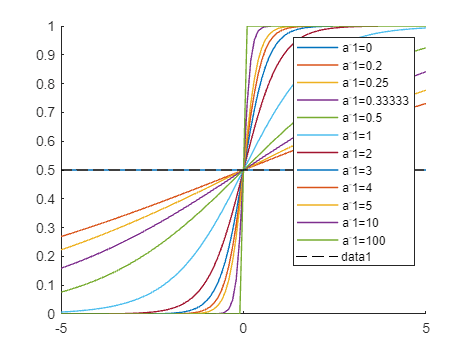

figure(1)
clf
x = -5:0.1:5;
hold on
for i=[0 1/5 1/4 1/3 1/2 1 2 3 4 5 10 100]
    y = 1./(1+exp(-i*x));
    plot(x,y,'LineWidth',1,DisplayName=append('a^-1=',num2str(i)))
end
plot([x(1) x(end)], [0.5 0.5],'k--')
hold off
legend

### Parameter x0

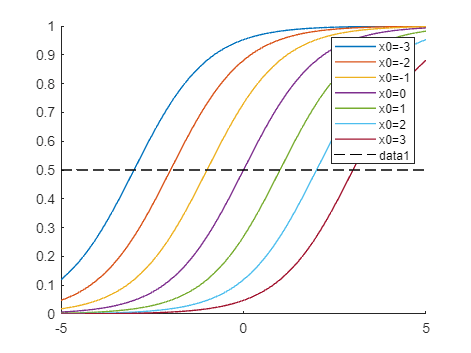

figure(2)
clf
x = -5:0.1:5;
hold on
for x0=[-3 -2 -1 0 1 2 3]
    y = 1./(1+exp(-(x-x0)));
    plot(x,y,'LineWidth',1,DisplayName=append('x0=',num2str(x0)))
end
plot([x(1) x(end)], [0.5 0.5],'k--')
hold off
legend

## Odds ratio

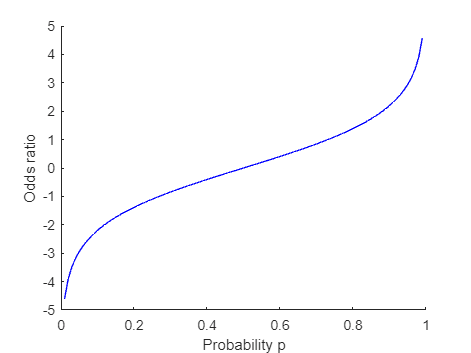

p = 0:0.01:1;
y=log(p./(1-p));

figure(3)
clf
x=-10:0.1:10;
hold on
plot(p,y,'b-')
xlabel('Probability p')
ylabel('Odds ratio')
hold off